# **demo17 of Im2mesh package**

demo17 - Refine mesh

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function poly2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Overview

Please take a look at demo14 or demo15 before starting demo17.

There are several methods to refine mesh:

- Refine mesh by splitting all elements

- Refine mesh in specific regions

- Refine mesh near boundary

We have demostrated how to refine mesh near boundary in demo16. 

In demo17, we will show method 1 and method 2.

Note that demo17 only works for MESH2D. If you use Gmsh as mesh generator, please refer to the following video on how to refine mesh locally.

[https://www.youtube.com/watch?v=GL6GUoIwSdU](https://www.youtube.com/watch?v=GL6GUoIwSdU)

We will achieve method 1 and method 2 via parameter settings of function poly2mesh.

Function poly2mesh has 6 input arguments. The last input argument 'opt' is optional.

- **opt** - a structure array. It is the options for poly2mesh. It stores extra parameter settings for poly2mesh.

- **opt.tf_smooth** - Boolean. Value: 0 or 1. Whether improve triangulation quality by adjusting the vertex positions and mesh topology. Default value: 1

- **opt.num_split** - number of splitting for refining mesh. Each triangle is split into four new sub-triangles. Default value: 0

- **opt.local_max** - n-by-2 array, used to specify max mesh size in a part. '[2, 0.5; 3, 0.15]' means that max mesh size in part 2 is 0.5; max mesh size in part 3 is 0.15. When set as [], this parameter will be ignored. Default value: []

- **opt.disp** - verbosity. Set as 'inf' to mute verbosity. Default value: 10

We will use 'opt.num_split' to refine mesh by splitting all elements.

We will use 'opt.local_max' to refine mesh in specific regions.

## Example 1. Refine mesh by splitting all elements

Create polyshape

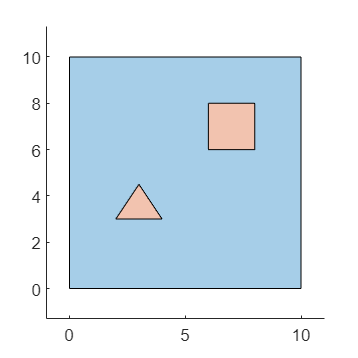

% create polyshape
vert1 = 10 * [ 0 0; 1 0; 1 1; 0 1 ];
ps1 = polyshape(vert1);

vert2 = [2 3] + [0 0; 2 0; 1 1.5];
ps2 = polyshape(vert2);

vert3 = [6 6] + 2*[ 0 0; 1 0; 1 1; 0 1 ];
ps3 = polyshape(vert3);

psB = union( ps2, ps3 );
psA = subtract( ps1, psB );
psCell = { psA; psB };

% plot psCell
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

We saw that there are 2 parts (or 2 phases): psCell{1} and psCell{2}

### Without splitting

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

[ poly_node, poly_edge ] = getPolyNodeEdge( bounds );

Generate mesh

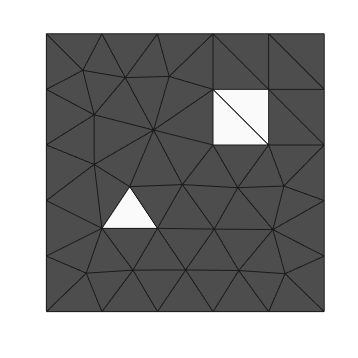

hmax = 2; 
mesh_kind = 'delaunay';
grad_limit = 0.25;

opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Refine by splitting (once)

We can split all elements by setting 'opt.num_split = 1;'

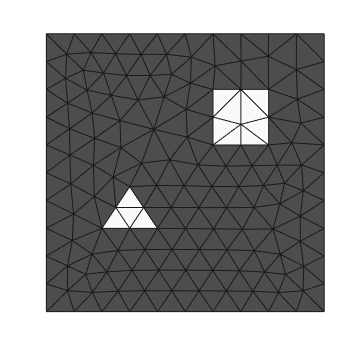

opt = [];
opt.disp = inf;     % silence verbosity
opt.num_split = 1;  % refine mesh by splitting elements

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Refine by splitting (twice)

We can split all elements further by setting 'opt.num_split = 2;'

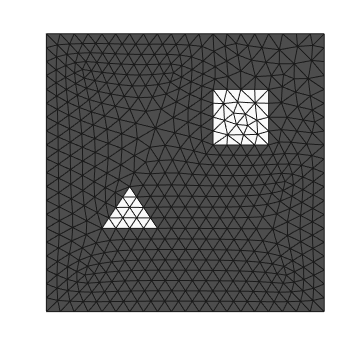

opt = [];
opt.disp = inf;     % silence verbosity
opt.num_split = 2;  % refine mesh by splitting elements

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

## Example 2. Refine mesh in specific parts

We will do this by setting 'opt.local_max'

Create pristine mesh for comparision.

hmax = 2; 
mesh_kind = 'delaunay';
grad_limit = 0.25;

opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Max mesh size = 0.5

Suppose we want to refine the mesh in part 2 (or phase 2).

'opt.local_max = [2, 0.5];' means that the maximum mesh size in part 2 is 0.5.

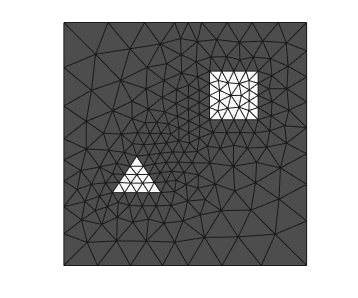

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [2, 0.5];

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Max mesh size = 0.25

We can further refine.

'opt.local_max = [2, 0.25];' means that the maximum mesh size in part 2 is 0.25.

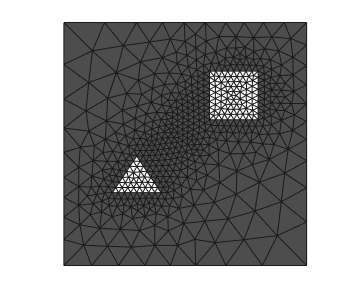

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [2, 0.25];

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

## Example 3. Refine mesh in specific regions

What if we want to refine a specific region in a part?

We will have to specify the interested region as a new part.

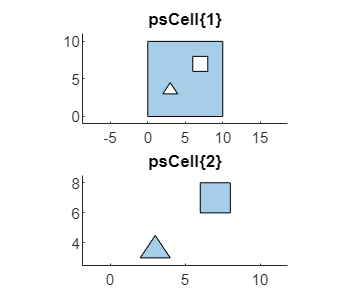

figure
for i = 1: length(psCell)
    subplot(2,1,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

We saw that part 2 - psCell{2} has two regions: square and triangles.

Suppose we want to refine mesh in the square region of part 2.

### Extract region

We can use matlab built-in function regions to extract region from polyshape.

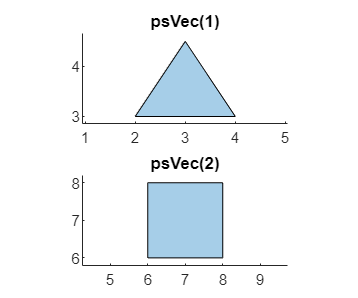

% psVec is a vector of polyshape
psVec = regions( psCell{2} ); 

figure
for i = 1: length(psVec)
    subplot(2,1,i);
    plot( psVec(i) );  axis equal;
    title(['psVec(' num2str(i), ')']);
end

psVec(2) is the square we interested in.

### Specify as a new part

We use boolean operations to make psVec(2) become a new part in psCell

psNew = psVec(2);

% remove overlap
for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psNew );
end

% add to the end of psCell
psCell{end+1} = psNew;

Plot

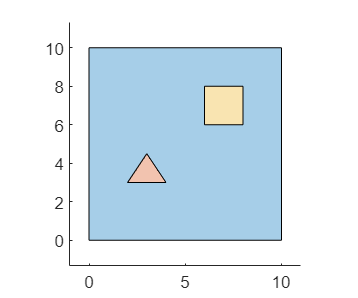

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

Plot one by one

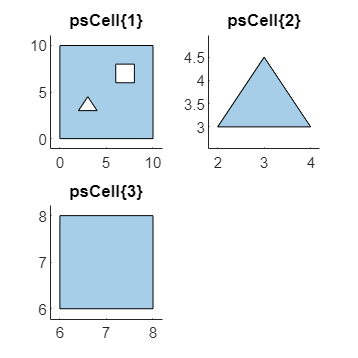

figure
for i = 1: length(psCell)
    subplot(2,2,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

The square we interested in is now part 3 (psCell{3})

### Refine mesh in part 3

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

[ poly_node, poly_edge ] = getPolyNodeEdge( bounds );

Generate mesh.

'opt.local_max = [3, 0.25];' means that the max mesh size in part 3 is 0.25.

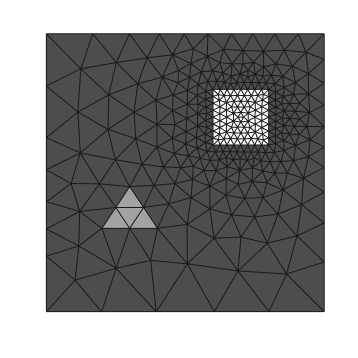

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [3, 0.25];

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Refine in multiple parts

'opt.local_max = [2, 0.15; 3, 0.25];' means that the max mesh size in part 2 is 0.15; the max mesh size in part 3 is 0.25.

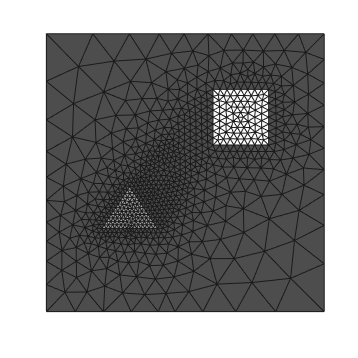

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [2, 0.15; 3, 0.25];

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

clearvars

## Example 4. Refine mesh locally

Create polyshape

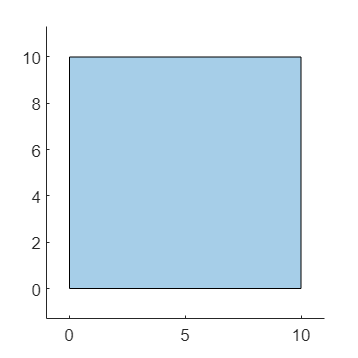

% square
vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

plot(psSq); axis equal

Generate mesh

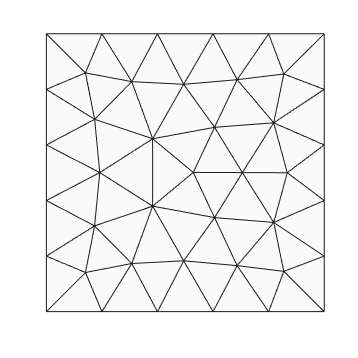

psCell = {psSq};    % a cell array of polyshape
bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

[ poly_node, poly_edge ] = getPolyNodeEdge( bounds );

hmax = 2; 
mesh_kind = 'delaunay';
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Region of interest

Suppose we want to refine the mesh in the upper right corner of the square.

Let's locate the region of interest (ROI) using polyshape. 

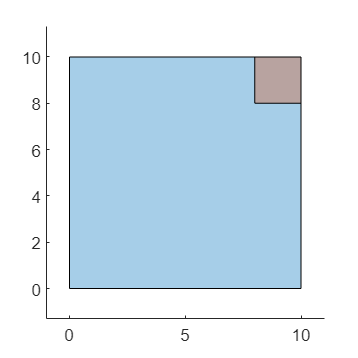

vertex = [8, 8] + 2*[ 0 0; 1 0; 1 1; 0 1 ];
psROI = polyshape(vertex);

figure; axis equal
hold on
for i = 1: length(psCell)
    plot(psCell{i});
end

plot(psROI);
hold off

### Specify as a new part

We use boolean operations to make psROI become a new part in psCell

psNew = psROI;

% remove overlap
for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psNew );
end

% add to the end of psCell
psCell{end+1} = psNew;

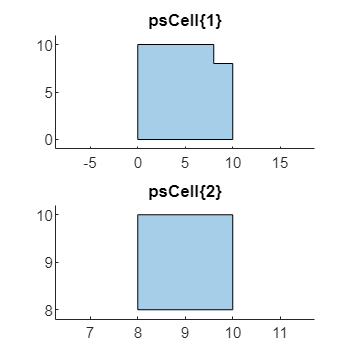

figure
for i = 1: length(psCell)
    subplot(2,1,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

### Generate mesh

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

[ poly_node, poly_edge ] = getPolyNodeEdge( bounds );

Create pristine mesh for comparision.

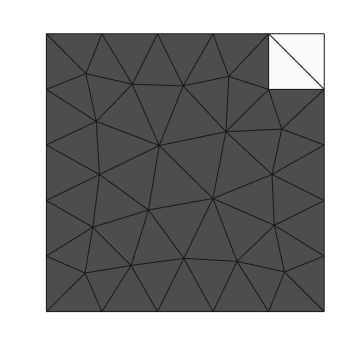

hmax = 2;
mesh_kind = 'delaunay';
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Refine mesh

We can refine the mesh in the upper right corner.

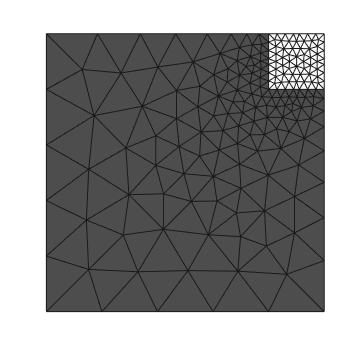

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [2, 0.3];

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

We can assign identical part label (or phase label).

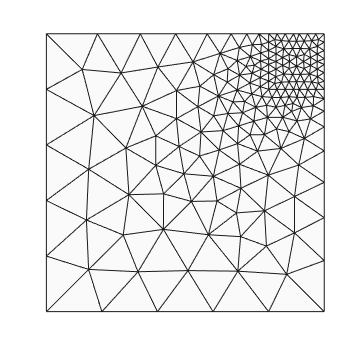

tnum(tnum == 2) = 1;
plotMeshes(vert,tria,tnum);

clearvars

## Example 5. Refine mesh locally

Load image

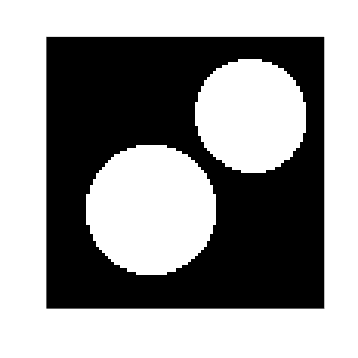

im = imread('Circle2.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Convert image to polygonal boundary

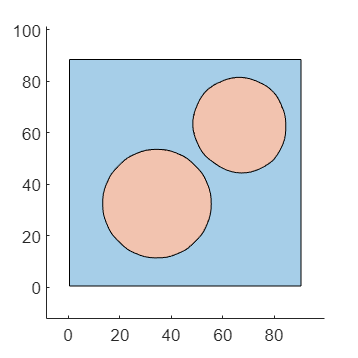

opt = [];   % reset opt
opt.tolerance = 0.05;
opt.tf_mesh = false;
bounds = im2mesh( im, opt );
psCell = bound2polyshape(bounds);

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

### Region of interest

Suppose we want to refine the mesh in the middle. 

Let's locate the region of interest (ROI) using polyshape. 

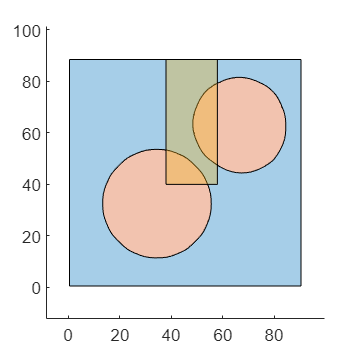

vertex = [38, 88.5; 58, 88.5; 58, 40; 38 40 ];
psROI = polyshape(vertex);

figure; axis equal
hold on
for i = 1: length(psCell)
    plot(psCell{i});
end

plot(psROI);
hold off

### Specify as new parts

We use boolean operations to make psROI become new parts in psCell

psNew = psROI;
psC_inters = psCell;

% find intersect
for i = 1: length(psCell)
    psC_inters{i} = intersect( psCell{i}, psNew );
end

% delete empty elements in cell array
psC_inters = psC_inters( ~cellfun('isempty', psC_inters) );

% remove overlap
for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psNew );
end

% append psC_inters to the end of psCell
psCell = [ psCell; psC_inters ];

Plot

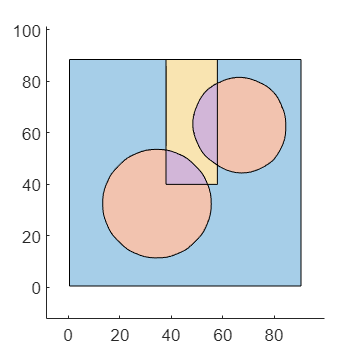

figure; axis equal
hold on
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

Plot one by one

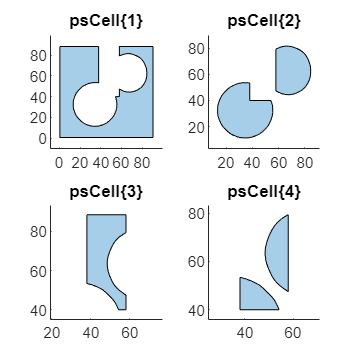

figure
for i = 1: length(psCell)
    subplot(2,2,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

psCell{3} and psCell{4} are newly added.

### Generate mesh

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

bounds = getCtrlPnts( bounds, false );
tolerance = 0.06;
bounds = simplifyBounds( bounds, tolerance );

[ poly_node, poly_edge ] = getPolyNodeEdge( bounds );

Create pristine mesh for comparision.

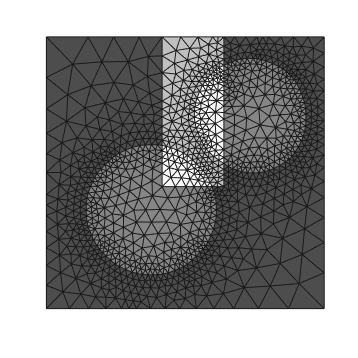

hmax = 500;
mesh_kind = 'delaunay';
grad_limit = 0.25;

opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

Zoom in

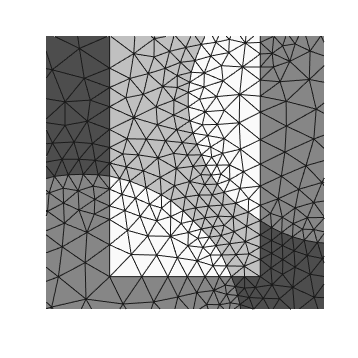

plotMeshes(vert,tria,tnum);

xlim([29.6 66.5])
ylim([35.7 71.9])

### Refine mesh

We can refine the mesh in the region of interest.

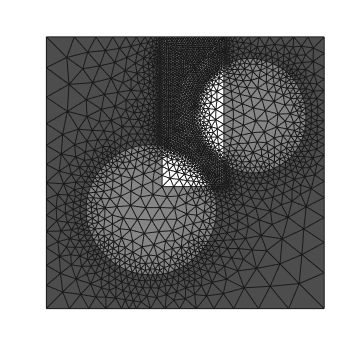

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [3, 0.8];

[ vert,tria,tnum ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit, opt );
plotMeshes(vert,tria,tnum);

Zoom in

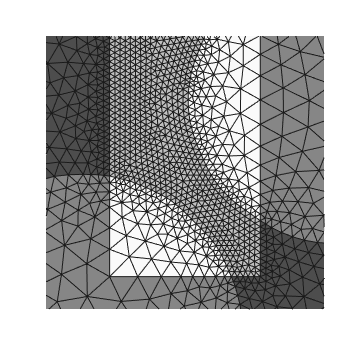

plotMeshes(vert,tria,tnum);

xlim([29.6 66.5])
ylim([35.7 71.9])

We can re-assign part label.

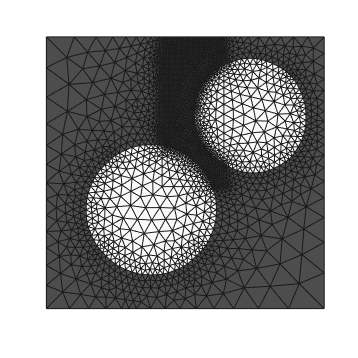

tnum(tnum == 4) = 2;
tnum(tnum == 3) = 1;
plotMeshes(vert,tria,tnum);

Zoom in

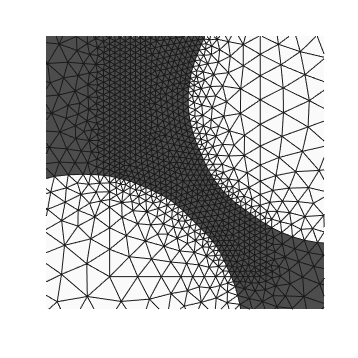

plotMeshes(vert,tria,tnum);

xlim([29.6 66.5])
ylim([35.7 71.9])

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo